# Simulation for Inverted Pendulum

`Author: Eduardo Fernandes Montesuma`

`Date: 30/03/2018`

clear;
clc;

## Constants

M   = 4.800;    % Cart mass
m   = 0.356;    % Pendulum mass
L   = 0.560;    % Pole length
bth = 0.035;    % Joint Friction
bx  = 4.900;    % Cart Friction
I   = 0.006;    % Pole inertia moment
g   = 9.806;    % Gravitational acceleration

## Nonlinear system simulation

to = 0; tF = 50; sampling = 1000;

t = linspace(to, tF, sampling);
[~,y] = ode23s(@nonlinear_equations, t, [0 0 0 0]);

## Step response

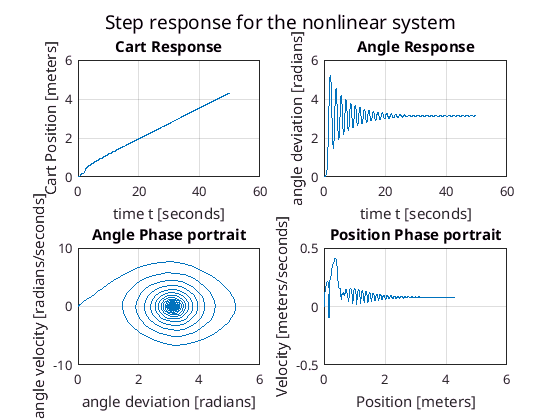

figure();
% Cart Position
ax1 = subplot(2,2,1);
plot( t, y(:,1) );
grid(ax1, 'on');
title('Cart Response');
ylabel('Cart Position [meters]');
xlabel('time t [seconds]');

% Angle deviation
ax2 = subplot(2,2,2);
plot( t, y(:,3) );
grid(ax2, 'on');
title('Angle Response');
ylabel('angle deviation [radians]');
xlabel('time t [seconds]');

% Phase portrait
ax3 = subplot(2,2,3);
plot( y(:,3), y(:,4) );
grid(ax3, 'on');
title('Angle Phase portrait');
ylabel('angle velocity [radians/seconds]');
xlabel('angle deviation [radians]');

% Phase portrait
ax4 = subplot(2,2,4);
plot( y(:,1), y(:,2) );
grid(ax4, 'on');
title('Position Phase portrait');
ylabel('Velocity [meters/seconds]');
xlabel('Position [meters]');

suptitle('Step response for the nonlinear system')

## Linear system simulation

[A_unstab, B_unstab] = linear_CartPend(M, m, L, I, bx, bth, 0); % Simulation around pi

     0



[A_stable, B_stable] = linear_CartPend(M, m, L, I, bx, bth, 1); % Simulation around pi
C = eye(4);
D = zeros(4,1);

ss_unst = ss(A_unstab, B_unstab, C, D);
ss_stab = ss(A_stable, B_stable, C, D);

ss_unst


ss_unst =
 
  A = 
             x1        x2        x3        x4
   x1         0         1         0         0
   x2         0    -1.017    0.6876  -0.01231
   x3         0         0         0         1
   x4         0    -1.723     17.78   -0.3184
 
  B = 
           u1
   x1       0
   x2  0.2075
   x3       0
   x4  0.3517
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.



ss_stab


ss_stab =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2        0   -1.017  -0.6876  0.01231
   x3        0        0        0        1
   x4        0    1.723   -17.78  -0.3184
 
  B = 
            u1
   x1        0
   x2   0.2075
   x3        0
   x4  -0.3517
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.



## Unstable Step response

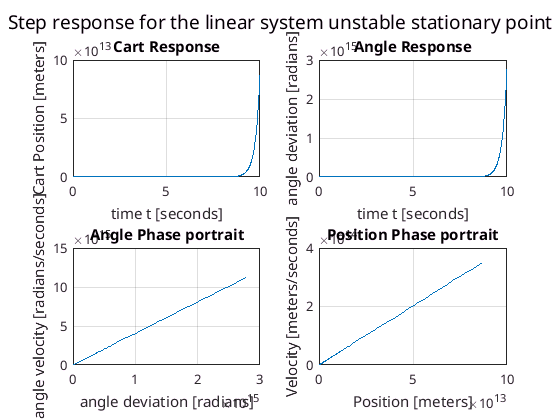

t_lin = linspace(0,10,1000);
[y_linear,~] = step(ss_unst,t_lin);
figure()

% Cart Position
ax1 = subplot(2,2,1);
plot( t_lin, y_linear(:,1) );
grid(ax1, 'on');
title('Cart Response');
ylabel('Cart Position [meters]');
xlabel('time t [seconds]');

% Angle deviation
ax2 = subplot(2,2,2);
plot( t_lin, y_linear(:,3) );
grid(ax2, 'on');
title('Angle Response');
ylabel('angle deviation [radians]');
xlabel('time t [seconds]');

% Phase portrait
ax3 = subplot(2,2,3);
plot( y_linear(:,3), y_linear(:,4) );
grid(ax3, 'on');
title('Angle Phase portrait');
ylabel('angle velocity [radians/seconds]');
xlabel('angle deviation [radians]');

% Phase portrait
ax4 = subplot(2,2,4);
plot( y_linear(:,1), y_linear(:,2) );
grid(ax4, 'on');
title('Position Phase portrait');
ylabel('Velocity [meters/seconds]');
xlabel('Position [meters]');

suptitle('Step response for the linear system unstable stationary point')

## Stable Step response

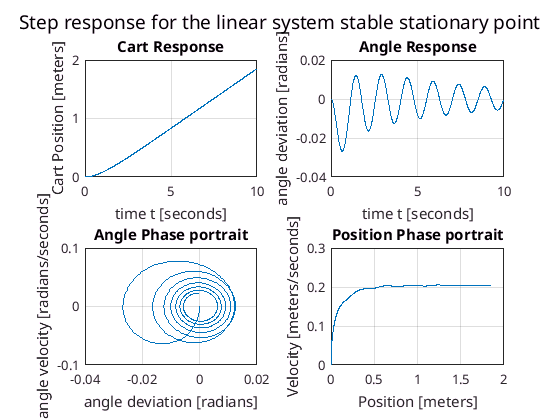

t_lin = linspace(0,10,1000);
[y_linear,~] = step(ss_stab,t_lin);
figure()

% Cart Position
ax1 = subplot(2,2,1);
plot( t_lin, y_linear(:,1) );
grid(ax1, 'on');
title('Cart Response');
ylabel('Cart Position [meters]');
xlabel('time t [seconds]');

% Angle deviation
ax2 = subplot(2,2,2);
plot( t_lin, y_linear(:,3) );
grid(ax2, 'on');
title('Angle Response');
ylabel('angle deviation [radians]');
xlabel('time t [seconds]');

% Phase portrait
ax3 = subplot(2,2,3);
plot( y_linear(:,3), y_linear(:,4) );
grid(ax3, 'on');
title('Angle Phase portrait');
ylabel('angle velocity [radians/seconds]');
xlabel('angle deviation [radians]');

% Phase portrait
ax4 = subplot(2,2,4);
plot( y_linear(:,1), y_linear(:,2) );
grid(ax4, 'on');
title('Position Phase portrait');
ylabel('Velocity [meters/seconds]');
xlabel('Position [meters]');

suptitle('Step response for the linear system stable stationary point')

## Linearized system eigenvalues

[A_unst, B_unst] = linear_CartPend(M, m, L, I, bx, bth, 0); % Simulation around 0

     0



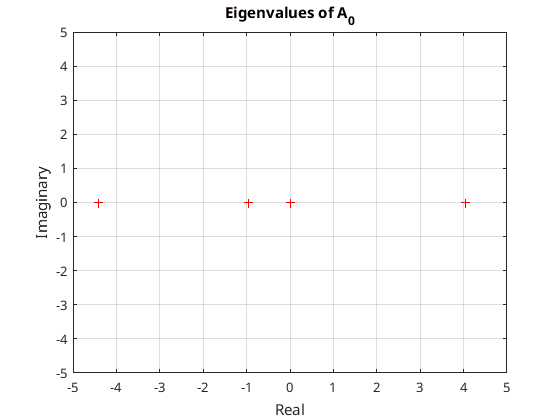

[A_stab, B_stab] = linear_CartPend(M, m, L, I, bx, bth, 1); % Simulation around 0

poles_unst = eig(A_unst);
poles_stab = eig(A_stab);

poles_unst = [poles_unst, zeros(4,1)];
%poles_stab = [poles_stab, zeros(4,1)];

figure();
plot(poles_unst(:,1), poles_unst(:,2),'r+');
title('Eigenvalues of A_0');
ylabel('Imaginary')
xlabel('Real')
grid();
xlim([-5,5]);
ylim([-5,5]);

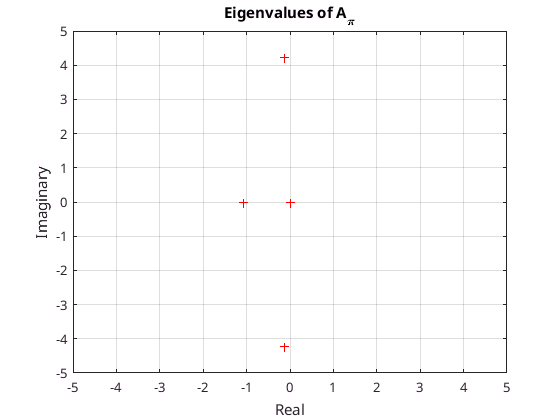


figure();
plot(poles_stab,'r+');
title('Eigenvalues of A_\pi');
ylabel('Imaginary')
xlabel('Real')
grid();
xlim([-5,5]);
ylim([-5,5]);